# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 14-Nov-2026 17:29:10

## Load Network Parameters

Load network parameters like weights, biases, or layers unsupported for network code generation from the stored parameters file.

params = load("./params_2026_11_14__17_29_03.mat");

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    imageInputLayer([224 224 3],"Name","Input_gpu_0|data_0","Normalization","zscore","Mean",params.Input_gpu_0_data_0.Mean,"StandardDeviation",params.Input_gpu_0_data_0.StandardDeviation)
    convolution2dLayer([3 3],24,"Name","node_1","Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.node_1.Bias,"Weights",params.node_1.Weights)
    batchNormalizationLayer("Name","node_2","Offset",params.node_2.Offset,"Scale",params.node_2.Scale,"TrainedMean",params.node_2.TrainedMean,"TrainedVariance",params.node_2.TrainedVariance)
    reluLayer("Name","node_3")
    maxPooling2dLayer([3 3],"Name","node_4","Padding",[1 1 1 1],"Stride",[2 2])];
net = addLayers(net,tempNet);

tempNet = [
    groupedConvolution2dLayer([1 1],28,4,"Name","node_5","Bias",params.node_5.Bias,"Weights",params.node_5.Weights)
    batchNormalizationLayer("Name","node_6","Offset",params.node_6.Offset,"Scale",params.node_6.Scale,"TrainedMean",params.node_6.TrainedMean,"TrainedVariance",params.node_6.TrainedVariance)
    reluLayer("Name","node_7")
    nnet.shufflenet.layer.ChannelShufflingLayer("shuffle_8to10",4)
    groupedConvolution2dLayer([3 3],1,112,"Name","node_11","Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.node_11.Bias,"Weights",params.node_11.Weights)
    batchNormalizationLayer("Name","node_12","Offset",params.node_12.Offset,"Scale",params.node_12.Scale,"TrainedMean",params.node_12.TrainedMean,"TrainedVariance",params.node_12.TrainedVariance)
    groupedConvolution2dLayer([1 1],28,4,"Name","node_13","Bias",params.node_13.Bias,"Weights",params.node_13.Weights)
    batchNormalizationLayer("Name","node_14","Offset",params.node_14.Offset,"Scale",params.node_14.Scale,"TrainedMean",params.node_14.TrainedMean,"TrainedVariance",params.node_14.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = averagePooling2dLayer([3 3],"Name","node_15","Padding",[1 1 1 1],"Stride",[2 2]);
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(2,"Name","node_16")
    reluLayer("Name","node_17")];
net = addLayers(net,tempNet);

tempNet = [
    groupedConvolution2dLayer([1 1],34,4,"Name","node_18","Bias",params.node_18.Bias,"Weights",params.node_18.Weights)
    batchNormalizationLayer("Name","node_19","Offset",params.node_19.Offset,"Scale",params.node_19.Scale,"TrainedMean",params.node_19.TrainedMean,"TrainedVariance",params.node_19.TrainedVariance)
    reluLayer("Name","node_20")
    nnet.shufflenet.layer.ChannelShufflingLayer("shuffle_21to23",4)
    groupedConvolution2dLayer([3 3],1,136,"Name","node_24","Padding",[1 1 1 1],"Bias",params.node_24.Bias,"Weights",params.node_24.Weights)
    batchNormalizationLayer("Name","node_25","Offset",params.node_25.Offset,"Scale",params.node_25.Scale,"TrainedMean",params.node_25.TrainedMean,"TrainedVariance",params.node_25.TrainedVariance)
    groupedConvolution2dLayer([1 1],34,4,"Name","node_26","Bias",params.node_26.Bias,"Weights",params.node_26.Weights)
    batchNormalizationLayer("Name","node_27","Offset",params.node_27.Offset,"Scale",params.node_27.Scale,"TrainedMean",params.node_27.TrainedMean,"TrainedVariance",params.node_27.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_28")
    reluLayer("Name","node_29")];
net = addLayers(net,tempNet);

tempNet = [
    groupedConvolution2dLayer([1 1],34,4,"Name","node_30","Bias",params.node_30.Bias,"Weights",params.node_30.Weights)
    batchNormalizationLayer("Name","node_31","Offset",params.node_31.Offset,"Scale",params.node_31.Scale,"TrainedMean",params.node_31.TrainedMean,"TrainedVariance",params.node_31.TrainedVariance)
    reluLayer("Name","node_32")
    nnet.shufflenet.layer.ChannelShufflingLayer("shuffle_33to35",4)
    groupedConvolution2dLayer([3 3],1,136,"Name","node_36","Padding",[1 1 1 1],"Bias",params.node_36.Bias,"Weights",params.node_36.Weights)
    batchNormalizationLayer("Name","node_37","Offset",params.node_37.Offset,"Scale",params.node_37.Scale,"TrainedMean",params.node_37.TrainedMean,"TrainedVariance",params.node_37.TrainedVariance)
    groupedConvolution2dLayer([1 1],34,4,"Name","node_38","Bias",params.node_38.Bias,"Weights",params.node_38.Weights)
    batchNormalizationLayer("Name","node_39","Offset",params.node_39.Offset,"Scale",params.node_39.Scale,"TrainedMean",params.node_39.TrainedMean,"TrainedVariance",params.node_39.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_40")
    reluLayer("Name","node_41")];
net = addLayers(net,tempNet);

tempNet = [
    groupedConvolution2dLayer([1 1],34,4,"Name","node_42","Bias",params.node_42.Bias,"Weights",params.node_42.Weights)
    batchNormalizationLayer("Name","node_43","Offset",params.node_43.Offset,"Scale",params.node_43.Scale,"TrainedMean",params.node_43.TrainedMean,"TrainedVariance",params.node_43.TrainedVariance)
    reluLayer("Name","node_44")
    nnet.shufflenet.layer.ChannelShufflingLayer("shuffle_45to47",4)
    groupedConvolution2dLayer([3 3],1,136,"Name","node_48","Padding",[1 1 1 1],"Bias",params.node_48.Bias,"Weights",params.node_48.Weights)
    batchNormalizationLayer("Name","node_49","Offset",params.node_49.Offset,"Scale",params.node_49.Scale,"TrainedMean",params.node_49.TrainedMean,"TrainedVariance",params.node_49.TrainedVariance)
    groupedConvolution2dLayer([1 1],34,4,"Name","node_50","Bias",params.node_50.Bias,"Weights",params.node_50.Weights)
    batchNormalizationLayer("Name","node_51","Offset",params.node_51.Offset,"Scale",params.node_51.Scale,"TrainedMean",params.node_51.TrainedMean,"TrainedVariance",params.node_51.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_52")
    reluLayer("Name","node_53")];
net = addLayers(net,tempNet);

tempNet = [
    groupedConvolution2dLayer([1 1],34,4,"Name","node_54","Bias",params.node_54.Bias,"Weights",params.node_54.Weights)
    batchNormalizationLayer("Name","node_55","Offset",params.node_55.Offset,"Scale",params.node_55.Scale,"TrainedMean",params.node_55.TrainedMean,"TrainedVariance",params.node_55.TrainedVariance)
    reluLayer("Name","node_56")
    nnet.shufflenet.layer.ChannelShufflingLayer("shuffle_57to59",4)
    groupedConvolution2dLayer([3 3],1,136,"Name","node_60","Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.node_60.Bias,"Weights",params.node_60.Weights)
    batchNormalizationLayer("Name","node_61","Offset",params.node_61.Offset,"Scale",params.node_61.Scale,"TrainedMean",params.node_61.TrainedMean,"TrainedVariance",params.node_61.TrainedVariance)
    groupedConvolution2dLayer([1 1],34,4,"Name","node_62","Bias",params.node_62.Bias,"Weights",params.node_62.Weights)
    batchNormalizationLayer("Name","node_63","Offset",params.node_63.Offset,"Scale",params.node_63.Scale,"TrainedMean",params.node_63.TrainedMean,"TrainedVariance",params.node_63.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = averagePooling2dLayer([3 3],"Name","node_64","Padding",[1 1 1 1],"Stride",[2 2]);
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(2,"Name","node_65")
    reluLayer("Name","node_66")];
net = addLayers(net,tempNet);

tempNet = [
    groupedConvolution2dLayer([1 1],68,4,"Name","node_67","Bias",params.node_67.Bias,"Weights",params.node_67.Weights)
    batchNormalizationLayer("Name","node_68","Offset",params.node_68.Offset,"Scale",params.node_68.Scale,"TrainedMean",params.node_68.TrainedMean,"TrainedVariance",params.node_68.TrainedVariance)
    reluLayer("Name","node_69")
    nnet.shufflenet.layer.ChannelShufflingLayer("shuffle_70to72",4)
    groupedConvolution2dLayer([3 3],1,272,"Name","node_73","Padding",[1 1 1 1],"Bias",params.node_73.Bias,"Weights",params.node_73.Weights)
    batchNormalizationLayer("Name","node_74","Offset",params.node_74.Offset,"Scale",params.node_74.Scale,"TrainedMean",params.node_74.TrainedMean,"TrainedVariance",params.node_74.TrainedVariance)
    groupedConvolution2dLayer([1 1],68,4,"Name","node_75","Bias",params.node_75.Bias,"Weights",params.node_75.Weights)
    batchNormalizationLayer("Name","node_76","Offset",params.node_76.Offset,"Scale",params.node_76.Scale,"TrainedMean",params.node_76.TrainedMean,"TrainedVariance",params.node_76.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_77")
    reluLayer("Name","node_78")
    reluLayer("Name","node_90")
    reluLayer("Name","node_102")
    reluLayer("Name","node_114")];
net = addLayers(net,tempNet);

tempNet = [
    groupedConvolution2dLayer([1 1],68,4,"Name","node_115","Bias",params.node_115.Bias,"Weights",params.node_115.Weights)
    batchNormalizationLayer("Name","node_116","Offset",params.node_116.Offset,"Scale",params.node_116.Scale,"TrainedMean",params.node_116.TrainedMean,"TrainedVariance",params.node_116.TrainedVariance)
    reluLayer("Name","node_117")
    nnet.shufflenet.layer.ChannelShufflingLayer("shuffle_118to120",4)
    groupedConvolution2dLayer([3 3],1,272,"Name","node_121","Padding",[1 1 1 1],"Bias",params.node_121.Bias,"Weights",params.node_121.Weights)
    batchNormalizationLayer("Name","node_122","Offset",params.node_122.Offset,"Scale",params.node_122.Scale,"TrainedMean",params.node_122.TrainedMean,"TrainedVariance",params.node_122.TrainedVariance)
    groupedConvolution2dLayer([1 1],68,4,"Name","node_123","Bias",params.node_123.Bias,"Weights",params.node_123.Weights)
    batchNormalizationLayer("Name","node_124","Offset",params.node_124.Offset,"Scale",params.node_124.Scale,"TrainedMean",params.node_124.TrainedMean,"TrainedVariance",params.node_124.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_125")
    reluLayer("Name","node_126")
    reluLayer("Name","node_138")
    reluLayer("Name","node_150")];
net = addLayers(net,tempNet);

tempNet = [
    groupedConvolution2dLayer([1 1],68,4,"Name","node_151","Bias",params.node_151.Bias,"Weights",params.node_151.Weights)
    batchNormalizationLayer("Name","node_152","Offset",params.node_152.Offset,"Scale",params.node_152.Scale,"TrainedMean",params.node_152.TrainedMean,"TrainedVariance",params.node_152.TrainedVariance)
    reluLayer("Name","node_153")
    nnet.shufflenet.layer.ChannelShufflingLayer("shuffle_154to156",4)
    groupedConvolution2dLayer([3 3],1,272,"Name","node_157","Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.node_157.Bias,"Weights",params.node_157.Weights)
    batchNormalizationLayer("Name","node_158","Offset",params.node_158.Offset,"Scale",params.node_158.Scale,"TrainedMean",params.node_158.TrainedMean,"TrainedVariance",params.node_158.TrainedVariance)
    groupedConvolution2dLayer([1 1],68,4,"Name","node_159","Bias",params.node_159.Bias,"Weights",params.node_159.Weights)
    batchNormalizationLayer("Name","node_160","Offset",params.node_160.Offset,"Scale",params.node_160.Scale,"TrainedMean",params.node_160.TrainedMean,"TrainedVariance",params.node_160.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = averagePooling2dLayer([3 3],"Name","node_161","Padding",[1 1 1 1],"Stride",[2 2]);
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(2,"Name","node_162")
    reluLayer("Name","node_163")
    reluLayer("Name","node_175")
    reluLayer("Name","node_187")
    reluLayer("Name","node_199")
    globalAveragePooling2dLayer("Name","node_200")
    fullyConnectedLayer(11,"Name","node_202","Bias",params.node_202.Bias,"Weights",params.node_202.Weights)
    softmaxLayer("Name","node_203")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"node_4","node_5");
net = connectLayers(net,"node_4","node_15");
net = connectLayers(net,"node_14","node_16/in1");
net = connectLayers(net,"node_15","node_16/in2");
net = connectLayers(net,"node_17","node_18");
net = connectLayers(net,"node_17","node_28/in2");
net = connectLayers(net,"node_27","node_28/in1");
net = connectLayers(net,"node_29","node_30");
net = connectLayers(net,"node_29","node_40/in2");
net = connectLayers(net,"node_39","node_40/in1");
net = connectLayers(net,"node_41","node_42");
net = connectLayers(net,"node_41","node_52/in2");
net = connectLayers(net,"node_51","node_52/in1");
net = connectLayers(net,"node_53","node_54");
net = connectLayers(net,"node_53","node_64");
net = connectLayers(net,"node_63","node_65/in1");
net = connectLayers(net,"node_64","node_65/in2");
net = connectLayers(net,"node_66","node_67");
net = connectLayers(net,"node_66","node_77/in2");
net = connectLayers(net,"node_76","node_77/in1");
net = connectLayers(net,"node_114","node_115");
net = connectLayers(net,"node_114","node_125/in2");
net = connectLayers(net,"node_124","node_125/in1");
net = connectLayers(net,"node_150","node_151");
net = connectLayers(net,"node_150","node_161");
net = connectLayers(net,"node_160","node_162/in1");
net = connectLayers(net,"node_161","node_162/in2");
net = initialize(net);

## Plot Layers

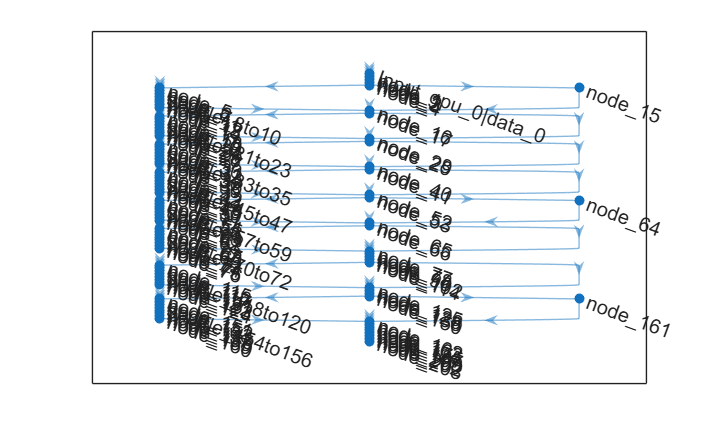

plot(net);